exercise 1

clc;
clear;
close all;

a = 1;
r = 1/4;

x = 1:20;
y = zeros(1, 20);

sum = 0;

for i = 1:20
    sum = sum + a * (r ^ (i-1));
    y(i) = sum;
end

exact = ones(1, 20) .* 4/3;

figure;

plot(x, y);
hold on;
plot(x, exact);

legend("approximate value", "actual value", Location="best");
xlabel("Iteration");
ylabel("Value");

exercise 2

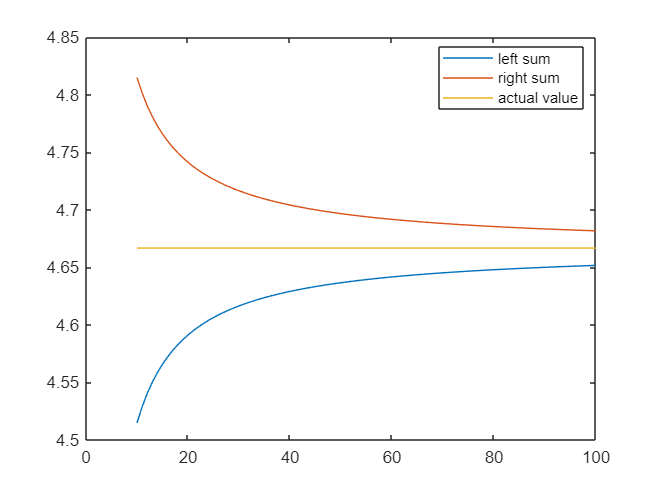

clc;
clear;
close all;

left_sums = [];
right_sums = [];

for n = 10:100
    a = 0;
    b = 3;
    
    delta_x = (b-a)/n;
    
    left_sum = 0;
    right_sum = 0;
    
    for k = 1:n
        xi_star = a + k*delta_x;
        xi_minus_one_star = a + (k-1)*(delta_x);
        
        right_sum = right_sum + sqrt(xi_star + 1) * delta_x;
        left_sum = left_sum + sqrt(xi_minus_one_star + 1) * delta_x;
    end

    left_sums(n-9) = left_sum;
    right_sums(n-9) = right_sum;
end

exact_value = ones(1, 91) .* 14 / 3;

x = 10:100;

plot(x, left_sums);
hold on;
plot(x, right_sums);
plot(x, exact_value);

legend("left sum", "right sum", "actual value", Location="best");